# Sygnals and Systems - Dr. Akhavan

## CA7 - Matin Bazrafshan

# Part 1

### 1.1


$$v_R \left(t\right)+v_L \left(t\right)+v_C \left(t\right)=v_{\textrm{in}} \left(t\right)$$
 

- 
$$v_R \left(t\right)=R\ldotp i\left(t\right)$$


- 
$$v_L \left(t\right)=L\ldotp \frac{\textrm{di}\left(t\right)}{\textrm{dt}}$$


- 
$$v_C \left(t\right)=\frac{1}{C}\int_{-\infty }^t i\left(z\right)\;d\;z$$



$$v_R \left(t\right)+v_L \left(t\right)+v_C \left(t\right)=v_{\textrm{in}} \left(t\right)\to \frac{d\left(v_R \left(t\right)+v_L \left(t\right)+v_C \left(t\right)\right)}{\textrm{dt}}=\frac{d\left(v_{\textrm{in}} \left(t\right)\right)}{\textrm{dt}}$$



$$\to R\ldotp \frac{d\left(i\left(t\right)\right)}{\textrm{dt}}+L\ldotp \frac{d^2 i\left(t\right)}{\textrm{dt}}+\frac{1}{C}i\left(t\right)=\frac{d\left(v\left(t\right)\right)}{t}$$


### 1.2


$$\textrm{RsI}\left(s\right)+{\textrm{Ls}}^2 I\left(s\right)+\frac{1}{C}I\left(s\right)=V\left(s\right)\to I\left(s\right)=\frac{V\left(s\right)}{\textrm{Rs}+{\textrm{Ls}}^2 +\frac{1}{C}}$$


### 1.3

- 
$$X\left(s\right)=V\left(s\right)$$


- 
$$Y\left(s\right)=\frac{1}{c}I\left(s\right)$$



$$\to Y\left(s\right)=\frac{X\left(s\right)}{\textrm{RsC}+{\textrm{Ls}}^2 C+1}$$


### 1.4

- 
$$R=1$$


- 
$$L=0\ldotp 25$$


- 
$$C=\frac{4}{3}$$



$$Y\left(s\right)=\frac{X\left(s\right)}{\frac{1}{3}s^2 +\frac{4}{3}s+1}=X\left(s\right)\left(\frac{3}{2}\frac{1}{s+1}-\frac{3}{2}\frac{1}{s+3}\right)$$


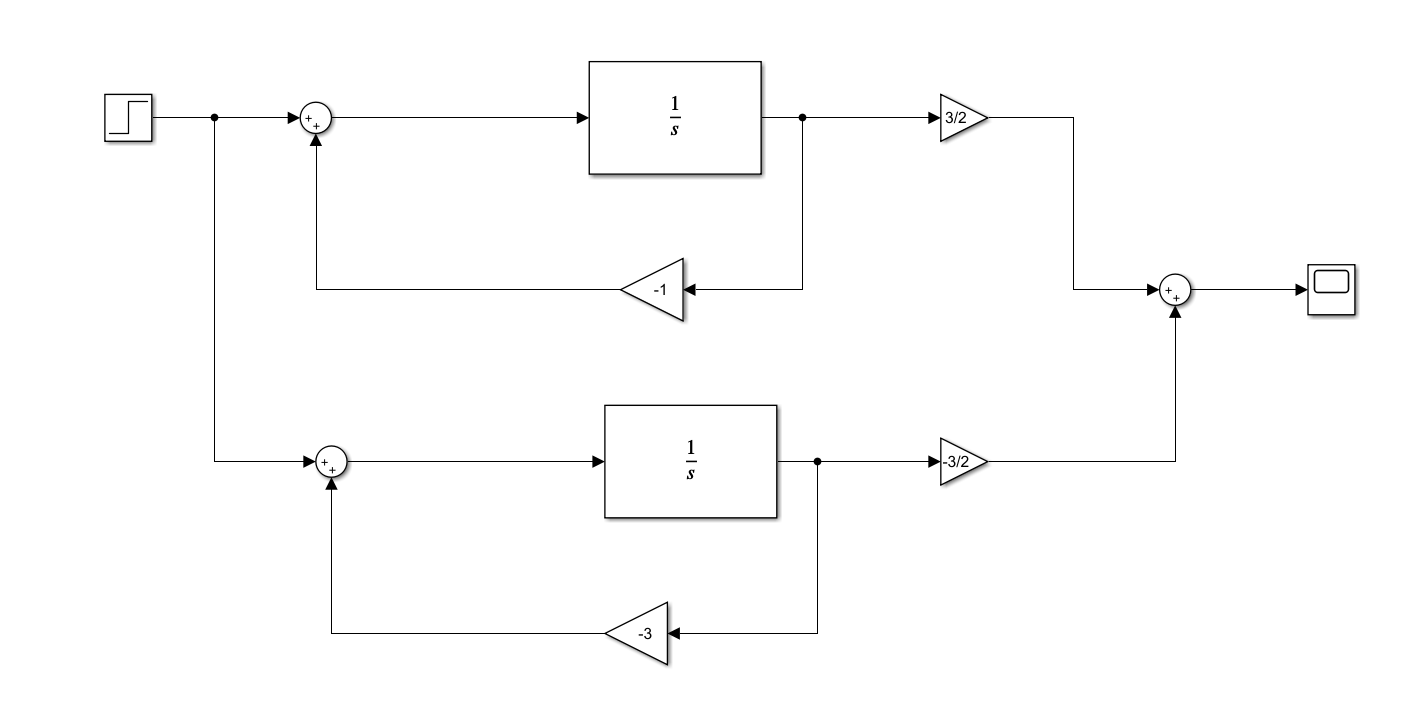    

### 1.5

- 
$$x\left(t\right)=u\left(t\right)\to X\left(s\right)=\frac{1}{s}$$



$$\to Y\left(s\right)=\frac{3}{s^3 +4s^2 +3s}=\frac{1}{s}+\frac{1}{2\left(s+3\right)}+-\frac{3}{2\left(s+1\right)}\to y\left(t\right)=\left(1+\frac{e^{-3t} }{2}-\frac{3e^{-t} }{2}\right)u\left(t\right)$$
     

### 1.6

yes, they are similar.

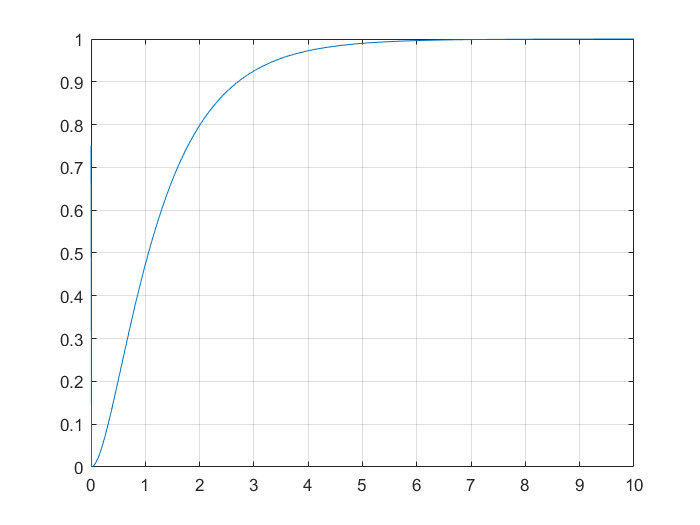

t = 0:0.01:10;
plot(t, 1 + exp(-3 * t) / 2 - 3 * exp(-t) / 2 .* heaviside(t));
grid on;

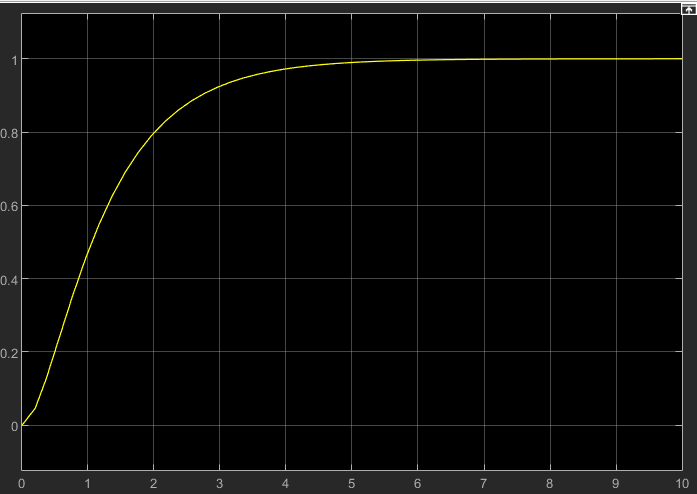

# Part 2

### 2.1

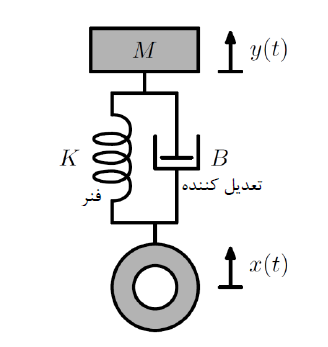


$$K\left(x\left(t\right)-y\left(t\right)\right)=B\left(\frac{\textrm{dx}\left(t\right)}{\textrm{dt}}-\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}\right)=M\frac{d^2 y\left(t\right)}{{\textrm{dt}}^2 }$$


- 
$$K=1$$


- 
$$M=1$$



$$B\;\frac{\textrm{dx}\left(t\right)}{\textrm{dt}}+x\left(t\right)=\frac{d^2 y\left(t\right)}{\textrm{dt}}+B\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}+y\left(t\right)$$


### 2.2

notation 1:


$$\textrm{BsX}\left(s\right)+X\left(s\right)=s^2 Y\left(s\right)+\textrm{BsY}\left(s\right)+Y\left(s\right)\to Y\left(s\right)=\frac{X\left(s\right)\left(\textrm{Bs}+1\right)}{s^2 +\textrm{Bs}+1}$$


notation 2:


$$\textrm{BsX}\left(s\right)+X\left(s\right)=s^2 Y\left(s\right)+\textrm{BsY}\left(s\right)+Y\left(s\right)\to Y\left(s\right)=\frac{1}{s^2 }\left(X\left(s\right)-Y\left(s\right)\right)+\frac{B}{s}\left(X\left(s\right)-Y\left(s\right)\right)$$


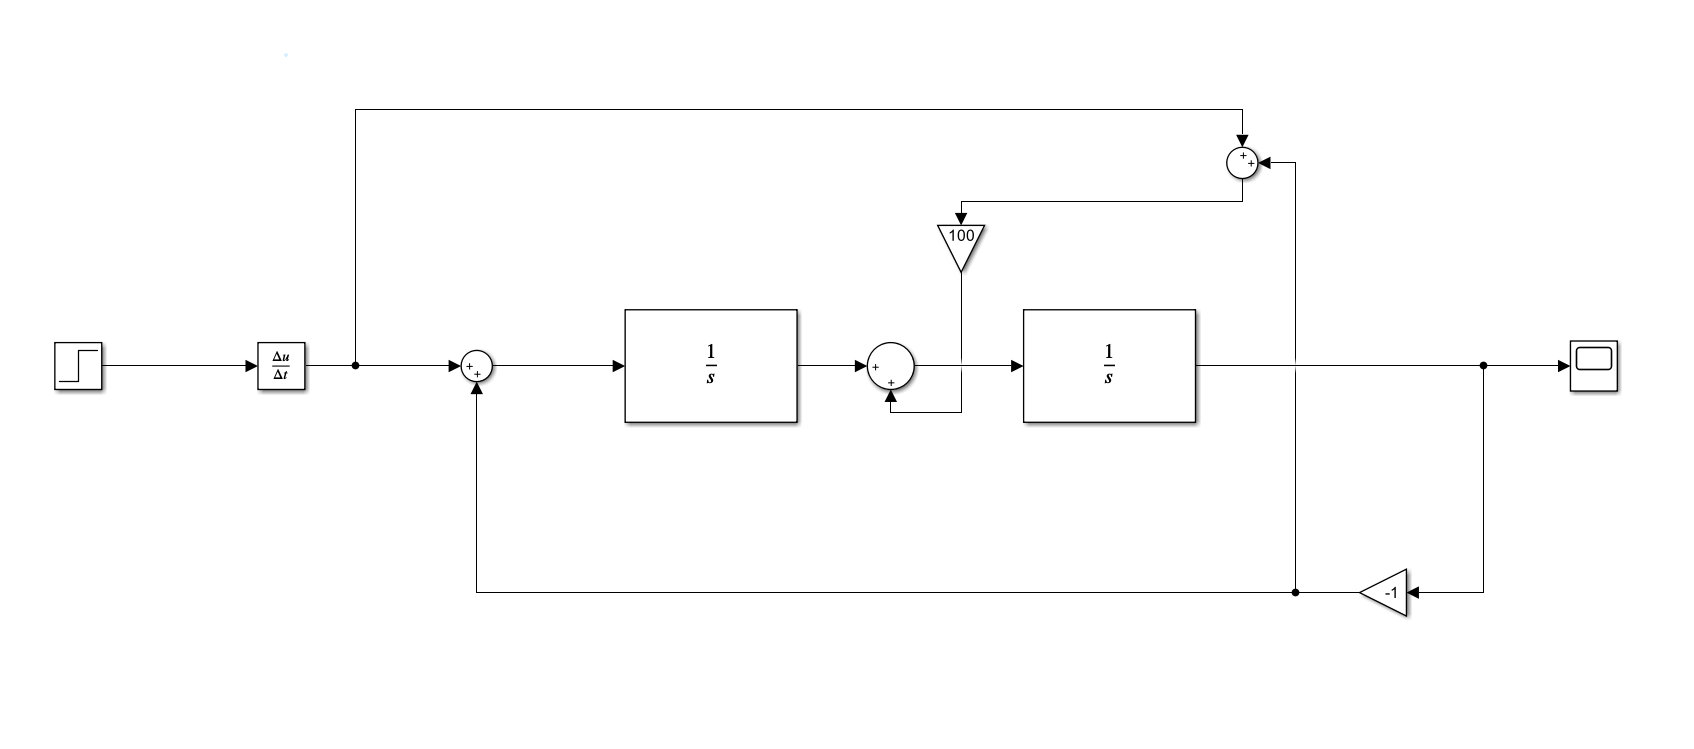

### 2.3

- 
$$x\left(t\right)=\delta \left(t\right)\to X\left(s\right)=1$$



$$\to Y\left(s\right)=\frac{\left(\textrm{Bs}+1\right)}{s^2 +\textrm{Bs}+1}$$


- 
$$B=0$$



$$\to Y\left(s\right)=\frac{1}{s^2 +1}$$



$$\to y\left(t\right)=\sin \left(t\right)$$


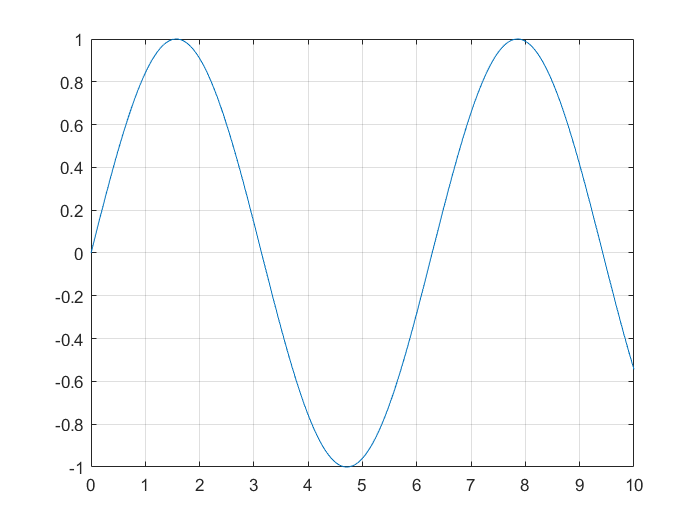

t = 0:0.01:10;
plot(t, sin(t));
grid on;

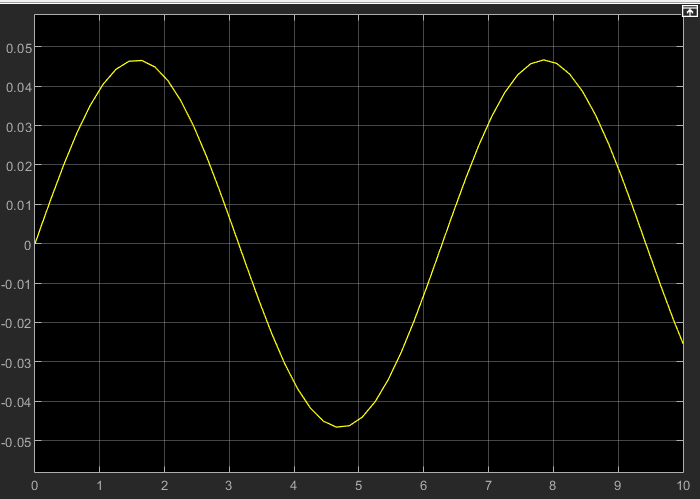

due to imaginary part, the cabin will oscillate forever, and never stops(sine function).

### 2.4

To avoid imaginary part. the roots of denominator must be all real, according to the quadric equation, the delta should be greater or equal to zero:


$$\Delta \ge 0\to B^2 -4\ge 0\to B\ge 2\to \min \left(B\right)=2$$



$$\to Y\left(s\right)=\frac{2s+1}{s^2 +2s+1}=\frac{2}{s+1}-\frac{1}{{\left(s+1\right)}^2 }$$


- 
$$\frac{d}{\textrm{ds}}\frac{1}{s+1}=-\frac{1}{{\left(s+1\right)}^2 }$$


- 
$$\frac{1}{s+1}\to e^{-t} u\left(t\right)$$



$$\to y\left(t\right)={-e}^{-t} \left(t-2\right)u\left(t\right)$$


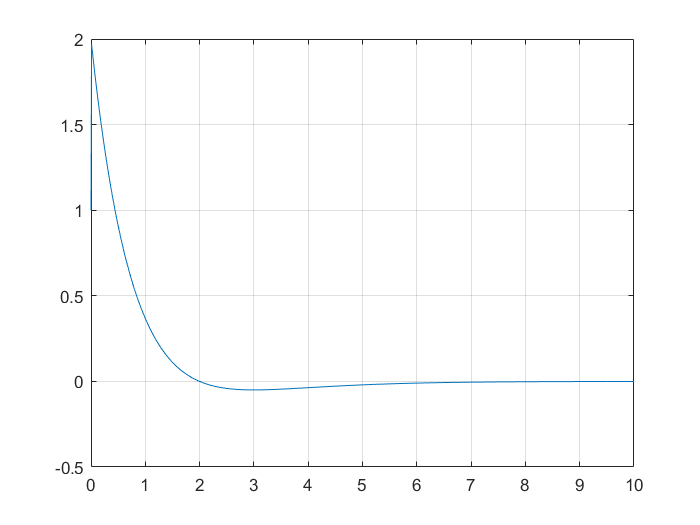

t = 0:0.01:10;
plot(t, -exp(-t) .* (t - 2) .* heaviside(t));
grid on;

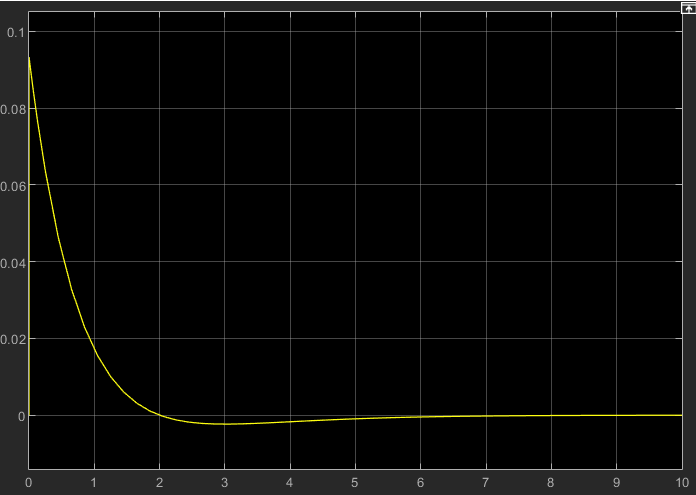

The cabin smothly stops over time.

### 2.5

- 
$$B=100$$
    


$$\to Y\left(s\right)=\frac{100s+1}{s^2 +100s+1}\approx \frac{100s+1}{s^2 +100\ldotp 1s+1}=\frac{100s+1}{\left(s+100\right)\left(s+0\ldotp 01\right)}=\frac{100}{s+100}$$


- 
$$\frac{\alpha }{\beta +s}\to {\alpha e}^{-\beta t} u\left(t\right)$$



$$\to y\left(t\right)=100e^{-100t} u\left(t\right)$$


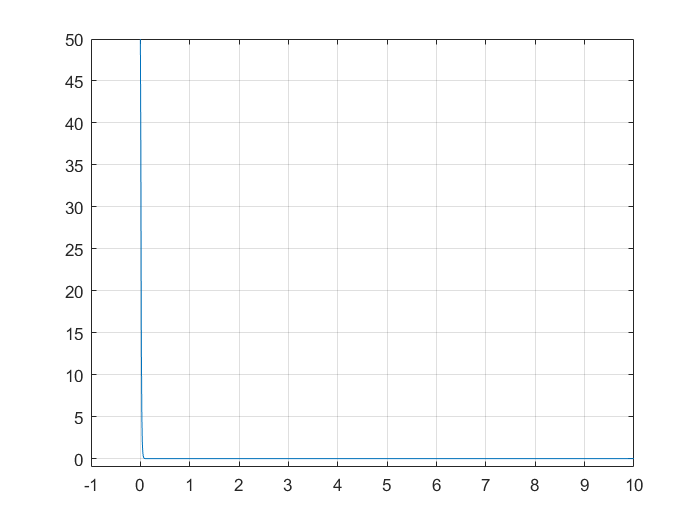

t = 0:0.01:10;
plot(t, 100 * exp(-100 * t) .* heaviside(t));
xlim([-1, 10]);
ylim([-1, 50]);
grid on;

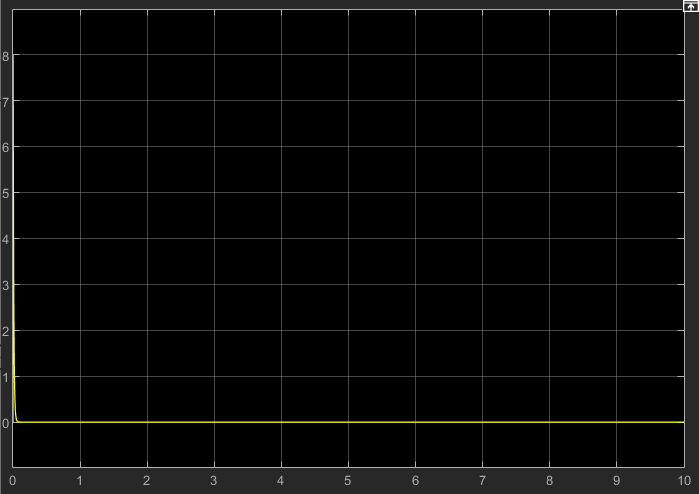

There will be a huge impluse(which take the most energy of cabin in a small part of time) and then the cabin rests.

### 2.6

It is obvious that $B=2$ is the best choise.

- $B=0$ will result in $\textrm{sine}$ and the car never stops.

- $B=100$ will cause a great impulse at the beginning.

- $B=2$ will smoothly stops so it is the nest choise.

Physical interpretation:

- because the change in momentum of cabin is constant ($v_2 =0\;\textrm{and}\;\textrm{so}\;m\Delta v=C$) so the impulse is equal in three given situtations, as we increase $\Delta t$, the stoping will be more smooth.

# part 3

### 3.1


$$\frac{d^2 y\left(t\right)}{{\textrm{dt}}^2 }\;3\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}+2y\left(t\right)=\left(t\right)\;$$


- 
$$x\left(t\right)=5u\left(t\right)$$


- 
$$y\left(0^- \right)=1$$


- 
$$y^{\prime } \left(0^- \right)=1$$



$${\to s}^2 Y\left(s\right)-s-1+3\left(\textrm{sY}\left(s\right)-1\right)+2Y\left(s\right)=X\left(s\right)$$



$$\to Y\left(s\right)=\frac{X\left(s\right)+s+4}{s^2 +3s+2}$$


- 
$$X\left(s\right)=\frac{5}{s}$$



$$\to Y\left(s\right)=\frac{s^2 +4s+5}{s^3 +3s^2 +2s}$$



$$\to Y=\frac{-2}{s+1}+\frac{-1}{2\left(s+2\right)}+\frac{5}{2s}\;$$



$$\to -\frac{1}{2}e^{-2t} -2e^{-t} +\frac{5}{2}$$


### 3.2

clearvars;
sys = tf(1,1);

syms y(t)
Dy = diff(y);

ode = (diff(y,t,2) + 3 * diff(y,t,1) + 2 * y) == 5 * step(sys);
cond1 = y(0) == 1;
cond2 = Dy(0) == 1;

conds = [cond1 cond2];
ySol(t) = dsolve(ode,conds);
ySol = simplify(ySol)
t = 0:0.01:10;

ySolFun = matlabFunction(ySol);

ySolValues = ySolFun(t);

plot(t, ySolValues)
xlabel('t')
ylabel('y(t)')

yes, we can see the results are similar.